Ejercicio 8 Teniendo en cuenta el diagrama de bloques DELTA. Completa la siguiente tabla y representa la potencia de ruido en función del tamaño del escalón. ¿Qué conclusiones se pueden extraer de la gráfica?

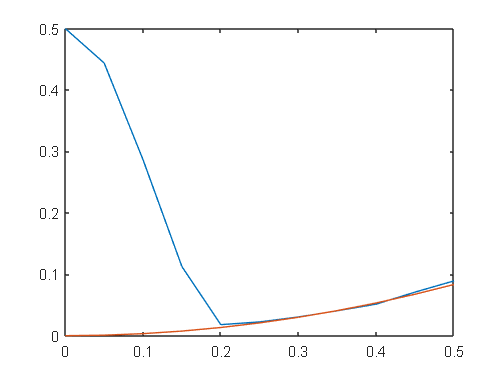

delta=0:0.05:0.5;
pot_ruido=[0.5,0.4439,0.2865,0.1126,0.01801,0.0224,0.0305,0.04057,0.05141,0.07097,0.08924];
plot(delta,pot_ruido,delta,delta.^2/3);

Ejercicio 10 Para el valor de escalón óptimo, modifica el factor de sobremuestreo alterando el parámetro ”diezma”, y observa su efecto sobre el ruido de cuantificación. Completa la siguiente tabla, representa la potencia de ruido en función del factor de sobremuestreo y extrae conclusiones. 

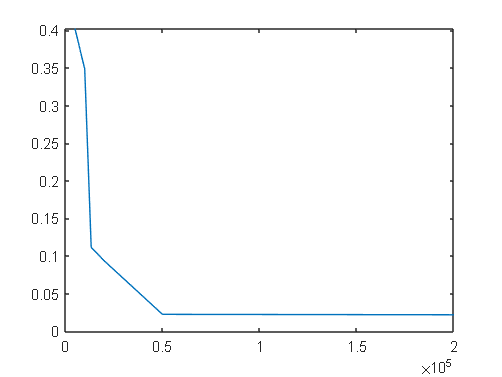

fs = [200000/40, 200000/20, 200000/15, 200000/10, 200000/4, 200000/1];
pot_ruido_ej_10 = [0.4024,0.3485, 0.1115,0.09363,0.0224,0.02183];
plot(fs,pot_ruido_ej_10);


% F =fs/fmin;      

## 4.3. Codificación paramétrica

En este apartado desarrollaremos la etapas de análisis y síntesis de un vocoder LPC simple, partiendo de una estructura básica definida en “vocLPC_incompleto.m”. Tendrás que finalizar el código contenido en este fichero ya sea completando líneas del mismo o programando alguna función.

## 4.5. Codificación de audio 

### 4.5.1. Modified Discrete Cosine Transform (MDCT) 

Ejercicio 13 En el fichero “fb_mdct” se ilustra la equivalencia entre la MDCT y un banco de filtros. Analiza el código y ejecútalo. 

Ejercicio 15 Ahora cuantificaremos la MDCT en el sistema anterior de forma muy burda ya que utilizaremos el mismo cuantificador y el mismo factor de escalado para todos los coeficientes de la MDCT. Para realizar la cuantificación utilizaremos la función “quantize”. Por ejemplo “w=quantize(z,5,’scale’)” devuelve los valores de z cuantificados con 5 bits y ajustando el valor de sobrecarga del cuantificador al máximo en valor absoluto de la señal. Añade al fichero del ejercicio anterior el código necesario para cuantificar la MDCT con 5 bits y realizar la reconstrucción a partir de la MDCT cuantificada. 